# Simulation parameters

### Plotting

fontsize=15; %for plotting

### Simulation

t_final=1e1;
sampling_time=0.1;%according to the description in [1]
time=0:sampling_time:t_final;

### MC channel

%This parameters are taken from [1, Sec. V]
L=5;%we fix the channel memory otherwise use -> %floor(pulse_duration/T_b);%channel memory


#### Interference level

Description: This block determines the symbol time according to the selected interference level. The interference level is measured with the parameter ITR as [1]

$\mathrm{ITR}(T_s)=\frac{A_\mathrm{ISI}}{A_\mathrm{SYM}+A_\mathrm{ISI}}=\frac{\int_{T_s}^\infty h(t)dt}{\int_{0}^\infty h(t)dt}$, and represented in Fig. 1.

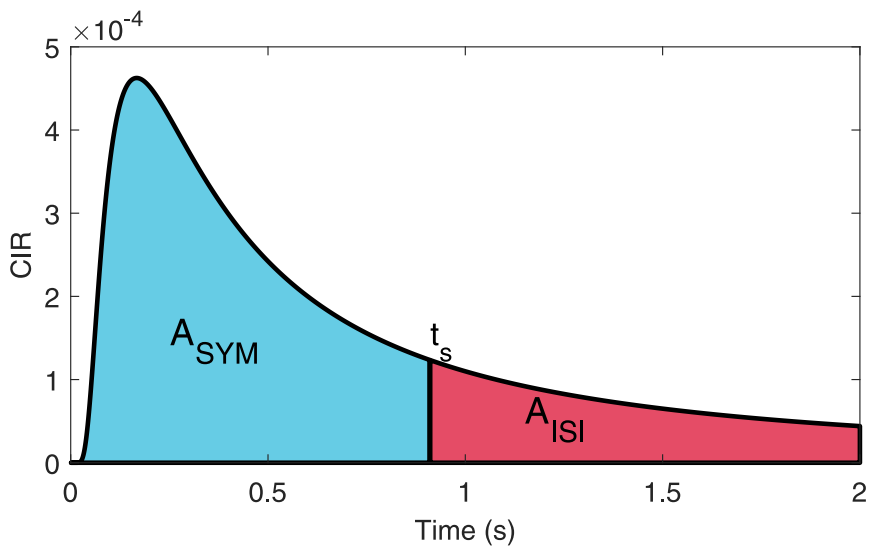

Fig. 1: Components for the ITR parameter [1].

ITR_vector=[60 55 50 45 40 35 30 25 20];%percentage of the ITR metric

load Datasets/testbed_pulse.mat %this mat files comprises the recording of a single pulse emitted by the sprayer in [2] 

A_total=trapz(pulse);%evaluating the total area
A_SYM=cumtrapz(pulse);%evaluating the area with the time index
ITR_Ts=A_SYM/A_total;%evaluating the ITR with the time index

%locating the time indexes
index=zeros(1,length(ITR_vector));
for i=1:length(ITR_vector)
    index(i)=find(ITR_Ts<ITR_vector(i)/100,1,'last');
end
%evaluating the corresponding bit time
T_b_vector=index*sampling_time;


### Plotting dataset sequence

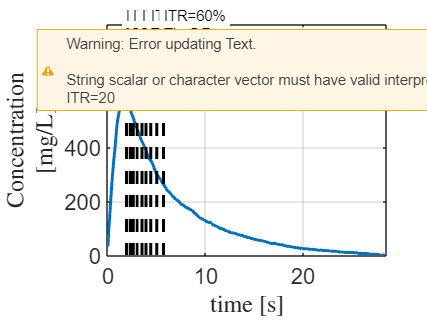

%plotting
figure;
time=(0:length(pulse)-1)*sampling_time;
plot(time,pulse,'LineWidth',2);grid on; hold on;
%plotting the symbol time vector
for i=1:length(T_b_vector)
    plot([T_b_vector(i) T_b_vector(i)],[0 1.5*max(pulse)],'--','LineWidth',2,'Color','black');
end
%plotting the annotations
for i=1:length(T_b_vector)
    str1=strcat('ITR=',num2str(ITR_vector(i)),'%');
    str2=strcat('Tb=',num2str(T_b_vector(i)),'s');
    if mod(i, 2) == 1
        text(T_b_vector(i),1.5*max(pulse),{str1,str2},'Interpreter','latex','BackgroundColor','white');
    else
        text(T_b_vector(i),1.1*max(pulse),{str1,str2},'Interpreter','latex','BackgroundColor','white');
    end
end
hold off;
xlabel('time [s]','Interpreter','latex');
ylabel({'Concentration','[mg/L]'},'Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([time(1) time(end) 0 1.5*max(pulse)]);
legend('Pulse shape','Symbol Time');

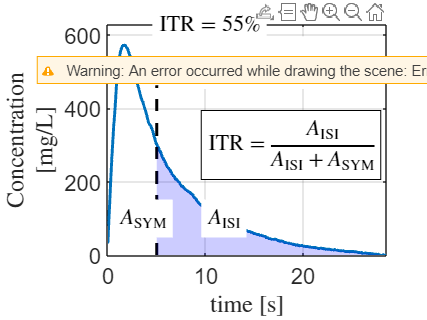

figure;
i=8;
time=(0:length(pulse)-1)*sampling_time;
plot(time,pulse,'LineWidth',2);grid on; hold on;

plot([T_b_vector(i) T_b_vector(i)],[0 1.5*max(pulse)],'--','LineWidth',2,'Color','black');

x=T_b_vector(i):sampling_time:time(end);
y=pulse(ceil(T_b_vector(i)/sampling_time)+1:end)';
x_fill = [x, fliplr(x)];
y_fill = [y, zeros(size(y))];

% Use fill to create the shaded area
fill(x_fill, y_fill, 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
hold off;
xlabel('time [s]','Interpreter','latex');
ylabel({'Concentration','[mg/L]'},'Interpreter','latex');


str1=strcat('$\mathrm{ITR}= ',num2str(ITR_vector(i)),'\%$');
str2=strcat('$T_b= ',num2str(T_b_vector(i)),'$s');
str3=strcat('$A_\mathrm{ISI}$');
str4=strcat('$A_\mathrm{SYM}$');
str5=strcat('$\mathrm{ITR}=\frac{A_\mathrm{ISI}}{A_\mathrm{ISI}+A_\mathrm{SYM}}$');
text(T_b_vector(i),1.1*max(pulse),str1,'Interpreter','latex','BackgroundColor','white','FontSize',fontsize);
text(T_b_vector(i),0.9*max(pulse),str2,'Interpreter','latex','BackgroundColor','white','FontSize',fontsize);
text(2*T_b_vector(i),100,str3,'Interpreter','latex','BackgroundColor','white','FontSize',fontsize);
text(T_b_vector(i)/5,100,str4,'Interpreter','latex','BackgroundColor','white','FontSize',fontsize);
text(2*T_b_vector(i),300,str5,'Interpreter','latex','BackgroundColor','white','FontSize',fontsize,'EdgeColor','black');

set(gca,'FontSize',fontsize);
axis([time(1) time(end) 0 1.1*max(pulse)]);
legend('Pulse shape','Symbol Time');

### Transmitter

total_bits=10^5;


### Trainning parameters

MaxEpochs=3;
MiniBatchSize=10;
LearnRate=1e-3;
% Training options
options = trainingOptions('adam', ...
    'MaxEpochs', MaxEpochs, ...
    'MiniBatchSize', MiniBatchSize, ...     % Process one sequence at a time
    'InitialLearnRate', LearnRate, ...
    'GradientThreshold', 1, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

### NN architectures

**Description**: This block define the layers of the NN architectures aiming to implement equal number of parameters among them.

#### **BiRNN**

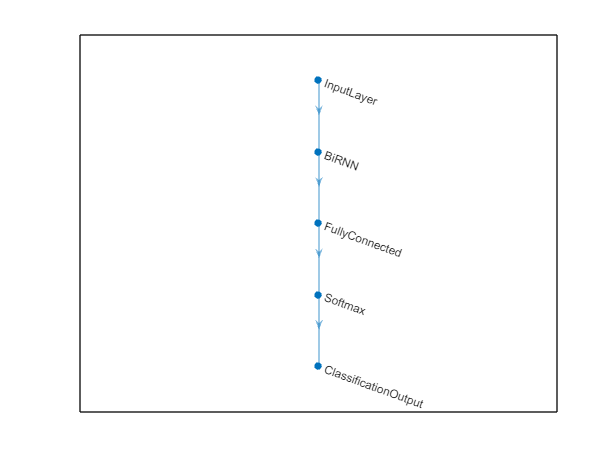

% Parameters
d_in = 1;      % Input dimension
n_units = 5;   % Number of hidden units in each RNN cell (for both forward and backward cells)
d_out = 2;     % Output dimension

% Define the layers
layers_BiRNN = [
    sequenceInputLayer(d_in, 'Name', 'InputLayer')                     % Input layer for sequences of dimension d_in
    bilstmLayer(n_units, 'OutputMode', 'Sequence', 'Name', 'BiRNN')        % Bidirectional RNN layer in sequence mode
    fullyConnectedLayer(d_out, 'Name', 'FullyConnected')                   % Fully connected layer to map to d_out classes
    softmaxLayer('Name', 'Softmax')                                        % Softmax layer for class probabilities
    classificationLayer('Name', 'ClassificationOutput')                    % Classification output layer
];

% Create the layer graph
lgraph_BiRNN = layerGraph(layers_BiRNN);

% Visualize the network
analyzeNetwork(lgraph_BiRNN);

figure;
plot(lgraph_BiRNN); grid on;

#### **RNN**

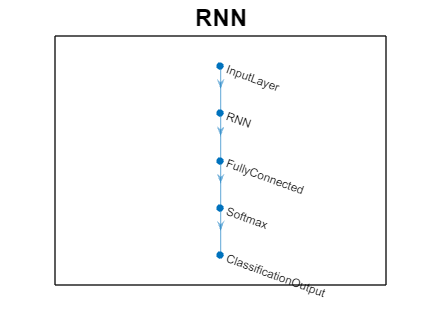

% Parameters
d_in = 1;      % Input dimension
n_units = 8;   % Number of hidden units in each RNN cell (for both forward and backward cells)
d_out = 2;     % Output dimension

% Define the layers
layers_RNN = [
    sequenceInputLayer(d_in, 'Name', 'InputLayer')                     % Input layer for sequences of dimension d_in
    lstmLayer(n_units, 'OutputMode', 'Sequence', 'Name', 'RNN')        % Bidirectional RNN layer in sequence mode
    fullyConnectedLayer(d_out, 'Name', 'FullyConnected')                   % Fully connected layer to map to d_out classes
    softmaxLayer('Name', 'Softmax')                                        % Softmax layer for class probabilities
    classificationLayer('Name', 'ClassificationOutput')                    % Classification output layer
];

% Create the layer graph
lgraph_RNN = layerGraph(layers_RNN);

% Visualize the network
analyzeNetwork(lgraph_RNN);

figure;
plot(lgraph_RNN); grid on;
set(gca,'FontSize',fontsize);
title("RNN");

#### **Feedforward NN**

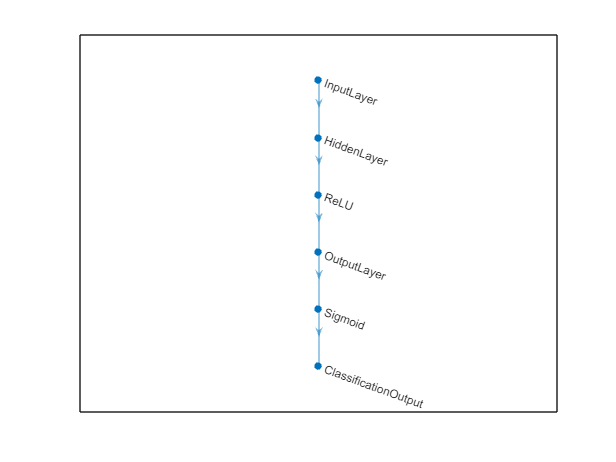

% Define the layers for the feedforward network with 302 trainable parameters
% Parameters
d_in_ffNN = 5;      % Input dimension
n_nodes = 38;   % Number of hidden units in each RNN cell (for both forward and backward cells)
d_out = 2;     % Output dimension
layers_ffNN = [
    featureInputLayer(d_in_ffNN, 'Name', 'InputLayer')                  % Input layer with 5 elements
    fullyConnectedLayer(n_nodes, 'Name', 'HiddenLayer')              % Hidden layer with 43 nodes
    reluLayer('Name', 'ReLU')                                   % ReLU activation for non-linearity
    fullyConnectedLayer(d_out, 'Name', 'OutputLayer')  % Single output node for binary classification
    sigmoidLayer('Name', 'Sigmoid')                % Sigmoid activation to get probability
    classificationLayer('Name', 'ClassificationOutput') % Classification layer               % Output layer with 1 node
];

% View the network structure
lgraph_ffNN = layerGraph(layers_ffNN);
analyzeNetwork(lgraph_ffNN);

figure;
plot(lgraph_ffNN); grid on;
set(gca,'FontSize',fontsize);
title("Feedforward NN");

#### **Temporal Convolutional Neural Network (TCN)**

**Description: **We take the design of the TCN network from ref [3]

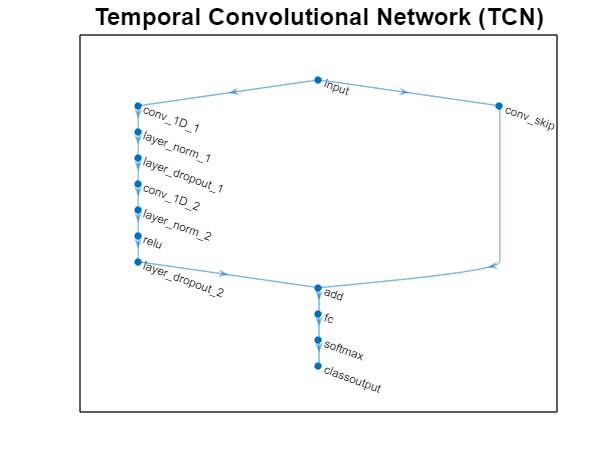

% Parameters
numFeatures = 1;
numClasses = 2;
numFilters = 6;
filterSize = 6;
dropoutFactor = 0.005;
numBlocks = 1;
addpath('NN');%adding this path for the SpatialDroputLayer definition

layer = sequenceInputLayer(numFeatures,Normalization="rescale-symmetric",Name="input");
lgraph_TCN = layerGraph(layer);

outputName = layer.Name;

for i = 1:numBlocks
    dilationFactor = 2^(i-1);
    
    layer = [
        convolution1dLayer(filterSize,numFilters,DilationFactor=dilationFactor,Padding="causal",Name="conv_1D_1")
        layerNormalizationLayer(Name="layer_norm_1")
        spatialDropoutLayer(dropoutFactor,"Name","layer_dropout_1")
        convolution1dLayer(filterSize,numFilters,DilationFactor=dilationFactor,Padding="causal",Name="conv_1D_2")
        layerNormalizationLayer(Name="layer_norm_2")
        reluLayer
        spatialDropoutLayer(dropoutFactor,"Name","layer_dropout_2")
        additionLayer(2,Name="add")];

    % Add and connect layers.
    lgraph_TCN = addLayers(lgraph_TCN,layer);
    lgraph_TCN = connectLayers(lgraph_TCN,outputName,"conv_1D_1");

    % Skip connection.
    if i == 1
        % Include convolution in first skip connection.
        layer = convolution1dLayer(1,numFilters,Name="conv_skip");

        lgraph_TCN = addLayers(lgraph_TCN,layer);
        lgraph_TCN = connectLayers(lgraph_TCN,outputName,"conv_skip");
        lgraph_TCN = connectLayers(lgraph_TCN,"conv_skip","add" + "/in2");
    else
        lgraph_TCN = connectLayers(lgraph_TCN,outputName,"add" + "/in2");
    end
    
    % Update layer output name.
    outputName = "add";
end

layer = [
    fullyConnectedLayer(numClasses,Name="fc")
    softmaxLayer
    classificationLayer];
lgraph_TCN = addLayers(lgraph_TCN,layer);
lgraph_TCN = connectLayers(lgraph_TCN,outputName,"fc");

% View the network structure
analyzeNetwork(lgraph_TCN);

figure;
plot(lgraph_TCN); grid on;
set(gca,'FontSize',fontsize);
title("Temporal Convolutional Network (TCN)");

save("NN/NN_layers.mat","lgraph_BiRNN","lgraph_RNN","lgraph_ffNN","lgraph_TCN");

Error using fontsize
Too many output arguments.

### References

[1] M. S. Kuran, H. B. Yilmaz, I. Demirkol, N. Farsad, and A. Goldsmith, ‘A Survey on Modulation Techniques in Molecular Communication via Diffusion’, *IEEE **Commun**. **Surv**. Tutorials*, vol. 23, no. 1, pp. 7–28, 2021, doi: [10.1109/COMST.2020.3048099](https://doi.org/10.1109/COMST.2020.3048099).

[2] Pit Hofmann, Jorge Torres Gómez, Frank H. P. Frank H.P. , Falko Dressler, April 27, 2023, "Dataset for Macroscale Molecular Communication Testbed", IEEE Dataport, doi: [https://dx.doi.org/10.21227/ytkm-xp81.](https://dx.doi.org/10.21227/ytkm-xp81.)

[3] Mathworks, [Sequence-to-Sequence Classification Using 1-D Convolutions](https://ch.mathworks.com/help/deeplearning/ug/sequence-to-sequence-classification-using-1-d-convolutions.html)